## (1) Theory BER SNR

clear,clc, close all
format long

N=1e3; % number of symbols
deltaN = N/10;
M = [2 4 8];
dB = linspace(0,25,N);% dB about SNR
dB2 = linspace(0,25,N/10);% dB2

symbol_rate = 10e9; % 10GHz
samples_per_symbol = 50; % 10 samples per symbol
T_symbol = 1/symbol_rate; % symbol period 1/10e9
Tw = T_symbol*N; % Total time window
samples = N*samples_per_symbol;
Deltat = Tw/samples; % time slot
t = 0:Deltat:Tw-Deltat;

Deltaf = 1/Tw; % frequency slot
Fs = 1/Deltat; % sample rate
Fmin = -Fs/2;
Fmax = Fs/2;
f = Fmin:Deltaf:Fmax-Deltaf; % frequency

for k = 1:length(M)
    Pb(k,:) = (2*M(k)-2)/M(k)*qfunc(sqrt(6/(M(k)^2-1)*10.^(dB/10))); % Lecture12 p22
end
for i = 1:length(dB)
    SNR = 10.^(dB(i)/10);
    Pook(i) = qfunc(sqrt(SNR));
end


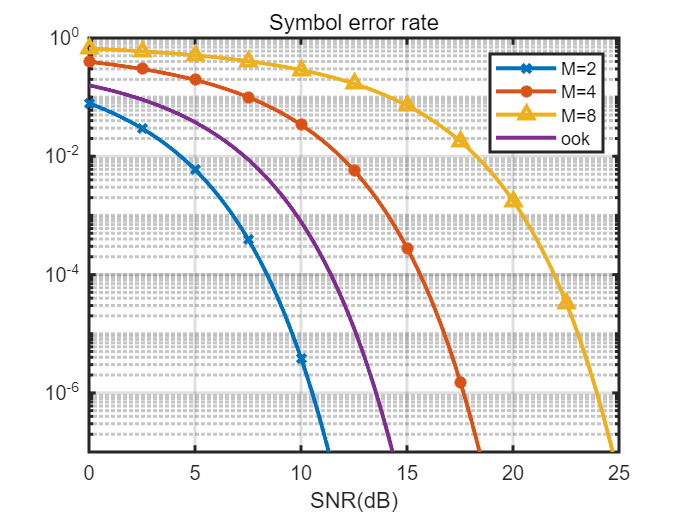

semilogy(dB,Pb(1,:),'LineWidth',2,'Marker','x','MarkerIndices',1:deltaN:N)
hold on
semilogy(dB,Pb(2,:),'LineWidth',2,'Marker','*',MarkerIndices=1:deltaN:N)
hold on
semilogy(dB,Pb(3,:),'LineWidth',2,'Marker','^',MarkerIndices=1:deltaN:N)
hold on
semilogy(dB,Pook,'LineWidth',2)
ylim([1.0000e-07, 1])
xlabel('SNR(dB)')
legend('M=2','M=4','M=8','ook')
title('Symbol error rate')
grid on
set(gca,'lineWidth',1.5)
hold off

for i = 1:3
    %     Pb_bit(i,:)=Pb(i,:)/(log2(M(i)));
    Pb_bit(i,:) = ((2*M(i)-2)/(M(i)*log2(M(i))))*qfunc(sqrt(10.^(dB/10).*((6*log2(M(i)))/(M(i)^2-1))));
end

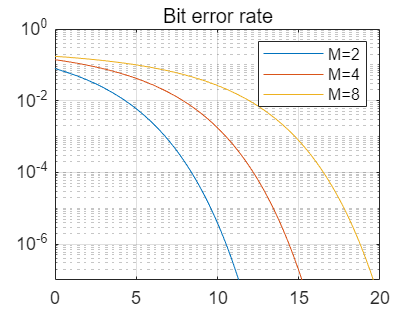

semilogy(dB,Pb_bit(1,:))
hold on
semilogy(dB,Pb_bit(2,:))
hold on
semilogy(dB,Pb_bit(3,:))
hold on
% semilogy(dB,Pook)
ylim([1.0000e-07, 1])
legend('M=2','M=4','M=8')
title('Bit error rate')
grid on
hold off

## (2) System without Volterra and MZM

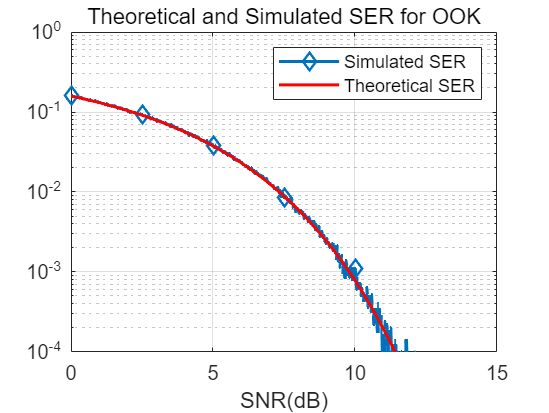

loopnum = 50;
% SNR range;
snr=10.^(dB/10); % SNR in W
delta = .2;
E_av = @(M) E*(M^2-1)/3;

% OOK
SER_ook = SER('OOK',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,SER_ook,'Marker','diamond','MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',1.5);hold on
semilogy(dB,Pook,'-r','LineWidth',1.5);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
title('Theoretical and Simulated SER for OOK')
legend('Simulated SER','Theoretical SER')
hold off

% OOK_ADC
SER_ook_ADC = SER('OOK_ADC',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,SER_ook_ADC,'Marker','diamond','MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',1.5);hold on
semilogy(dB,Pook,'-r','LineWidth',1.5);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
title('Theoretical and Simulated SER for OOK')
legend('Simulated SER','Theoretical SER')
hold off

% 2PAM
SER_2PAM = SER('2PAM',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,SER_2PAM,'Marker','diamond','MarkerIndices',1:deltaN:length(SER_2PAM),'LineWidth',1.5);hold on
semilogy(dB,Pb(1,:),'-r','LineWidth',1.5);
semilogy(dB,Pook,'Color','#EDB120','LineWidth',1.5);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
title('Theoretical and Simulated SER for 2PAM')
legend('Simulated 2PAM SER','Theoretical 2PAM SER','Theoretical OOK')
hold off

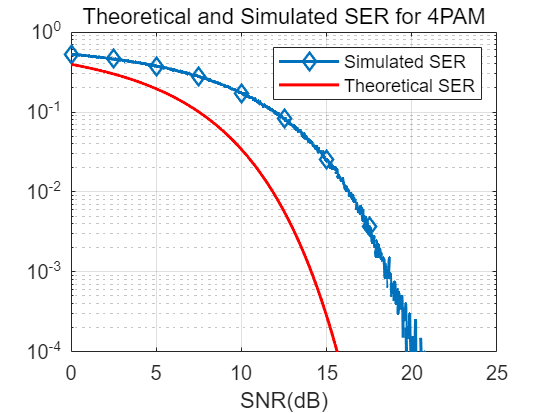

% 4PAM
SER_4PAM = SER('4PAM',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,SER_4PAM,'LineWidth',1.5,'Marker','diamond','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
title('Theoretical and Simulated SER for 4PAM')
legend('Simulated SER','Theoretical SER')
hold off

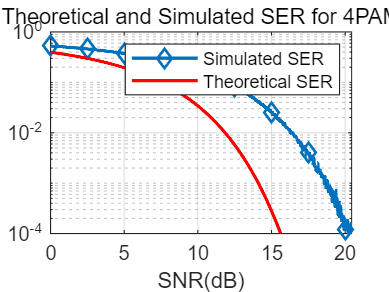

% 4PAM with ADC and DAC
SER_4PAM_ADC = SER('4PAM_ADC',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,SER_4PAM_ADC,'LineWidth',1.5,'Marker','diamond','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
title('Theoretical and Simulated SER for 4PAM')
legend('Simulated SER','Theoretical SER')
hold off

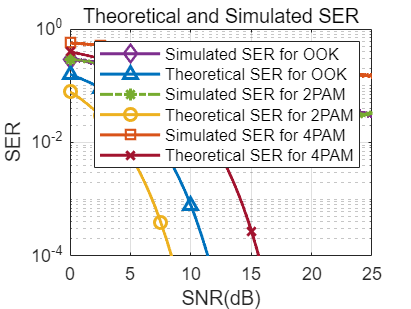

semilogy(dB,SER_ook,'Color','#7E2F8E','Marker','diamond','MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',1.5);hold on
semilogy(dB,Pook,'Color','#0072BD','Marker','^','MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',1.5);hold on;

semilogy(dB,SER_2PAM,'Color','#77AC30','Marker','*','MarkerIndices',1:deltaN:length(SER_2PAM),'LineWidth',1.5,'LineStyle','-.');hold on
semilogy(dB,Pb(1,:),'Color','#EDB120','Marker','o','MarkerIndices',1:deltaN:length(SER_2PAM),'LineWidth',1.5); hold on;

semilogy(dB,SER_4PAM,'Color','#D95319','LineWidth',1.5,'Marker','square','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'Color','#A2142F','LineWidth',1.5,'Marker','x','MarkerIndices',1:deltaN:N);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
title('Theoretical and Simulated SER')
legend('Simulated SER for OOK','Theoretical SER for OOK','Simulated SER for 2PAM','Theoretical SER for 2PAM','Simulated SER for 4PAM','Theoretical SER for 4PAM')
hold off

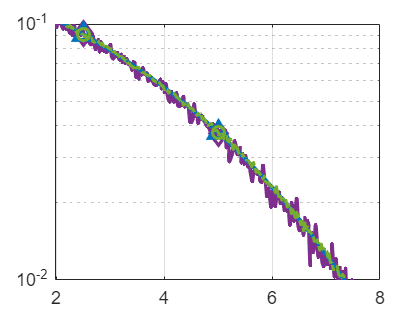

semilogy(dB,SER_ook,'Color','#7E2F8E','Marker','diamond','MarkerSize',8,'MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',2);hold on
semilogy(dB,Pook,'Color','#0072BD','Marker','^','MarkerSize',8,'MarkerIndices',1:deltaN:length(SER_ook),'LineWidth',2);hold on;

semilogy(dB,SER_2PAM,'Color','#77AC30','Marker','o','MarkerIndices',1:deltaN:length(SER_2PAM),'LineWidth',1.5,'LineStyle','-.');hold off
ylim([10^-2,10^-1])
grid on

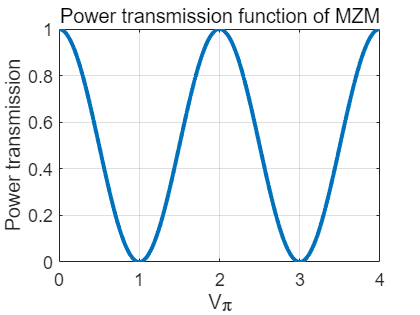

%% plot MZM transfer
x = 0:0.01:4;
y=cos(x*pi/2);
plot(x,y.^2,'LineWidth',2)
xlabel('V{\pi}')
ylabel('Power transmission')
title('Power transmission function of MZM')
grid on
hold off

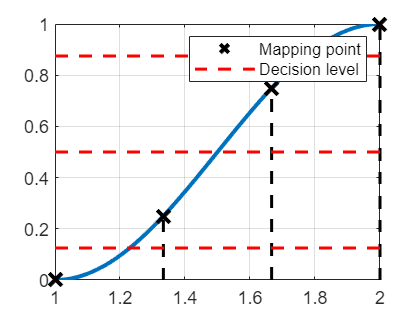

x = 1:0.01:2;
y=cos(x*pi/2).^2;
plot(x,y,'LineWidth',2)
ylim([0 1])
hold on
scatter(1,cos(1*pi/2).^2,80,'black','Marker','x','LineWidth',2)
hold on
scatter(1+1/3,cos((1+1/3)*pi/2).^2,80,'black','Marker','x','LineWidth',2)
hold on
scatter(1+2/3,cos((1+2/3)*pi/2).^2,80,'black','Marker','x','LineWidth',2)
hold on
scatter(1+3/3,cos((1+3/3)*pi/2).^2,80,'black','Marker','x','LineWidth',2)
hold on
line([1+1/3 1+1/3],[0 cos((1+1/3)*pi/2).^2],'LineWidth',1.5,'Color','black','LineStyle','--')
hold on
line([1+2/3 1+2/3],[0 cos((1+2/3)*pi/2).^2],'LineWidth',1.5,'Color','black','LineStyle','--')
hold on
line([2 2],[0 cos((2)*pi/2).^2],'LineWidth',1.5,'Color','black','LineStyle','--')
hold on

line([1 2],[1/8 1/8],'LineWidth',1.5,'Color','red','LineStyle','--')
hold on
line([1 2],[.5 .5],'LineWidth',1.5,'Color','red','LineStyle','--')
hold on
line([1 2],[1-1/8 1-1/8],'LineWidth',1.5,'Color','red','LineStyle','--')
hold on
grid on
legend('','','','','Mapping point','','','','Decision level')
hold off

## (3) System with MZM

E_av_mzm = @(M)((1/(M-1)/2)^2/3)*(M^2-1);

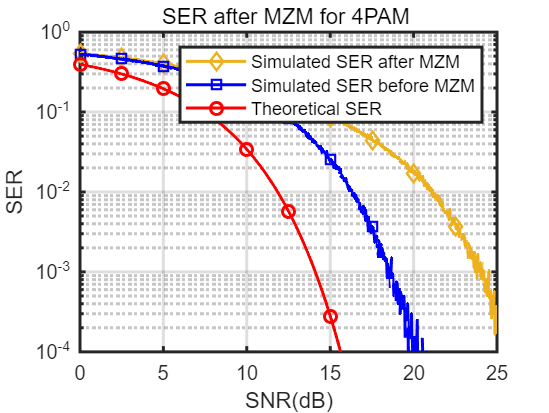

%% 4PAM_MZM

P_3_mzm = SER('4PAM_MZM',N,loopnum,dB,symbol_rate,samples_per_symbol);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(dB,P_3_mzm,'Color','#EDB120','LineWidth',1.5,'Marker','diamond','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,SER_4PAM,'Color','blue','LineWidth',1.5,'Marker','square','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5,'Marker','o','MarkerIndices',1:deltaN:N);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
title('SER after MZM for 4PAM ')
legend('Simulated SER after MZM','Simulated SER before MZM','Theoretical SER')
set(gca,'LineWidth',1.5)
hold off

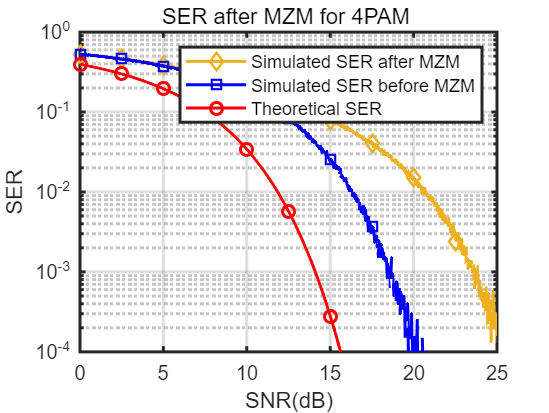

%% 4PAM_MZM_ADC

P_3_mzm_adc = SER('4PAM_MZM_ADC',N,loopnum,dB,symbol_rate,samples_per_symbol);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(dB,P_3_mzm_adc,'Color','#EDB120','LineWidth',1.5,'Marker','diamond','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,SER_4PAM,'Color','blue','LineWidth',1.5,'Marker','square','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5,'Marker','o','MarkerIndices',1:deltaN:N);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
title('SER after MZM for 4PAM ')
legend('Simulated SER after MZM','Simulated SER before MZM','Theoretical SER')
set(gca,'LineWidth',1.5)
hold off

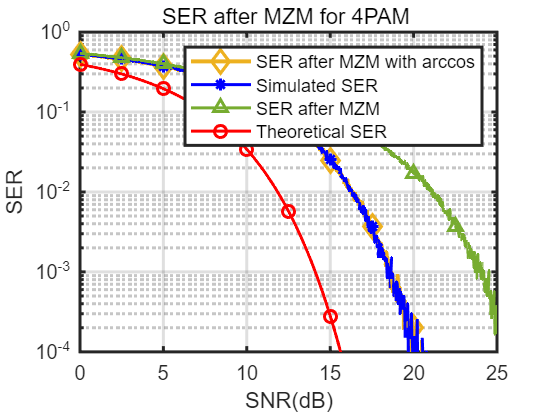

%% 4PAM with arccosin
P_3_mzm_arc = SER('4PAM_MZM_with_arccos',N,loopnum,dB,symbol_rate,samples_per_symbol);

semilogy(dB,P_3_mzm_arc,'Color','#EDB120','LineWidth',2,'Marker','diamond','MarkerIndices',1:deltaN:N,'MarkerSize',8);hold on
semilogy(dB,SER_4PAM,'Color','blue','LineWidth',1.5,'Marker','*','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,P_3_mzm,'Color','#77AC30','LineWidth',1.5,'Marker','^','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5,'Marker','o','MarkerIndices',1:deltaN:N);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
title('SER after MZM for 4PAM ')
legend('SER after MZM with arccos','Simulated SER','SER after MZM','Theoretical SER')
set(gca,'LineWidth',1.5)
hold off

% 4PAM
SER_4PAM = SER('4PAM',N,loopnum,dB,symbol_rate,samples_per_symbol);
%% 4PAM_MZM
P_3_mzm = SER('4PAM_MZM',N,loopnum,dB,symbol_rate,samples_per_symbol);
%% 4PAM_MZM_ADC
P_3_mzm_adc = SER('4PAM_MZM_ADC',N,loopnum,dB,symbol_rate,samples_per_symbol);
% ARC+ADC
P_3_mzm_arc_ADC = SER('4PAM_MZM_with_ADC_arccos',N,loopnum,dB,symbol_rate,samples_per_symbol);

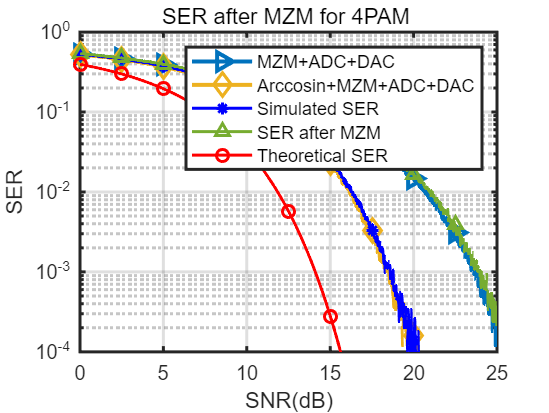

semilogy(dB,P_3_mzm_adc,'LineWidth',2,'Marker','>','MarkerIndices',1:deltaN:N,'MarkerSize',8);hold on
semilogy(dB,P_3_mzm_arc_ADC,'Color','#EDB120','LineWidth',2,'Marker','diamond','MarkerIndices',1:deltaN:N,'MarkerSize',8);hold on
semilogy(dB,SER_4PAM,'Color','blue','LineWidth',1.5,'Marker','*','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,P_3_mzm,'Color','#77AC30','LineWidth',1.5,'Marker','^','MarkerIndices',1:deltaN:N);hold on
semilogy(dB,Pb(2,:),'-r','LineWidth',1.5,'Marker','o','MarkerIndices',1:deltaN:N);grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
title('SER after MZM for 4PAM ')
legend('MZM+ADC+DAC','Arccosin+MZM+ADC+DAC','Simulated SER','SER after MZM','Theoretical SER')
set(gca,'LineWidth',1.5)
hold off

% % 8PAM
% x_4 = randi([0,7],1,N);
% % %%%%%%% bias %%%%%%%
% Vpi = 1;
% % A = 0;
% % B = 2;
% % di = (x_2-A)/B;
% %%%%%%%% MZM %%%%%%
% Vdc = 3;
% Vpp = 1; % Vout = [0,1]
%
% Vi = Vdc+Vpp*(x_4);
%
% Eout4 = (cos((pi/2)*(Vi/Vpi)));
%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%
% for i=1:length(dB);
%     N0=E(8)/snr(i);%计算噪声功率
%     N0_dB=10*log10(N0);%将噪声功率转换为dBW
%     ni=wgn(1,N,N0_dB);%产生高斯噪声
%     yR_4 = Eout4+ni;
%
%
%     for k = 1:length(yR_4)
%         if yR_4(k)< 1/2
%             y_detect_4(k) = 0;
%         elseif yR_4(k) < 3/2
%             y_detect_4(k) = 1;
%         elseif yR_4(k) < 5/2
%             y_detect_4(k) = 2;
%         elseif yR_4(k) < 7/2
%             y_detect_4(k) = 3;
%         elseif yR_4(k) < 9/2
%             y_detect_4(k) = 4;
%         elseif yR_4(k) < 11/2
%             y_detect_4(k) = 5;
%         elseif yR_4(k) < 13/2
%             y_detect_4(k) = 6;
%         else
%             y_detect_4(k) = 7;
%         end
%     end
%
%     bit_R_4=length(find(x_4~=y_detect_4));% Number of error bits
%     P_4_mzm(i)=bit_R_4/N;% SER
% end
% figure;
% semilogy(dB(1:deltaN:end),P_4_mzm(1:deltaN:end),'b*','LineWidth',1);hold on
% semilogy(dB,Pb(3,:),'-r','LineWidth',1.5);grid on;
% ylim([10^-3,1])
% hold off

## (4) With Volterra

N=1e3;
%% 4PAM
L = 5;
mu = 0.001;
loopnum = 500;
Vpi = 1;
mse_avg = 0;
% for n = 1:5
alpha4pam = [0 1 2 3];
x_3= randsrc(1,N,alpha4pam);
% x_3 = pulse_shape(N,symbol_rate,samples,x_3);
input = x_3/3;

A = N;
B = samples_per_symbol;
% input(input==1) = 1/3;
% input(input==2) = 2/3;
% input(input==3) = 1;
X = x_3;
Y = x_3;
w = rand(length(x_3),L);
x = rand(L,length(x_3));
mse = zeros(1,loopnum);
% Y = Vdc+Vpp*(x_3);
for i = 1:loopnum
    %%%%%%%%%%%%%%%%% MZM %%%%%%%%%%%%%%%%%%%%
    Vdc = 1;
    Vpp = 1/3; % Vout = [0,1]
    x_input = Y;
    %     Vi = Vdc+Vpp*(x_input);
    %
    %     Eout3 = (cos((pi/2)*(Vi/Vpi)));

    x_3_gauss = pulse_shape(N,symbol_rate,samples_per_symbol,x_input);
    x_3_gauss = Quantnoise_TX(x_3_gauss,A,B); % Quantnoise_Tx
    Vi = Vdc+Vpp*(x_3_gauss);
        
    Eout3 = (cos((pi/2)*(Vi/Vpi))).*conj(cos((pi/2)*(Vi/Vpi)));

    samplesPerSymbol = length(Eout3)/N;
    Eout3 = Eout3((samplesPerSymbol/2+1):samplesPerSymbol:end);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    for j=1:length(Eout3)
        X_shift = circshift(X,-j+1,2);
        for l = 1:L

            X_in = circshift(X_shift,l-1,2);
            x(l,j) = X_in(1);
        end
        Y(j) = sum(w(j,:)*x(:,j));
        e(j) = -Eout3(j)+input(j); % error calculate
        w(j,:) = w(j,:) + e(j)*mu*2*x(:,j)'; % parameter renewal
        Y(j) = sum(w(j,:)*x(:,j));
    end
    mse(i) = sum(abs(e.^2))/length(x_3);
    %     end
end
% mse_avg = mse+mse_avg;
% Y_avg(:,n) = Y;
% end

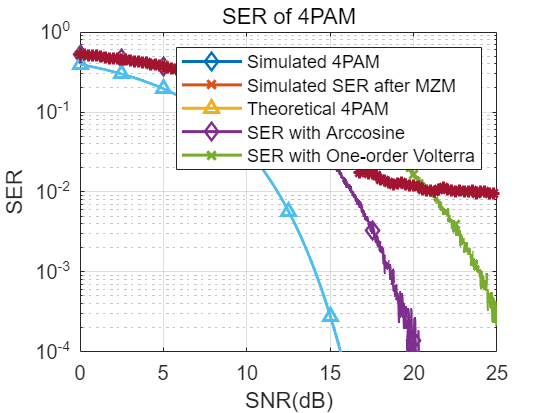


% %%%%%%% bias %%%%%%%
Vpi = 1;
% A = 0;
% B = 2;
% di = (x_2-A)/B;
%%%%%%%% MZM %%%%%%
Vdc = 1;
Vpp = 1/3; % Vout = [0,1]
% x_3_1 = w(:,1)'.*x_3;
P_3_mzm_vol_avg = 0;
y_detect_3 = 0;
loop = 10;
x_3_1 = Y;
Vi = Vdc+Vpp*(x_3_1);
Eout3 = (cos((pi/2)*(Vi/Vpi))).*conj(cos((pi/2)*(Vi/Vpi)));
Eav = mean(Eout3.^2);

x_3_1 = pulse_shape(N,symbol_rate,samples_per_symbol,Y);

x_3_1 = Quantnoise_TX(x_3_1,A,B); % Quantnoise_Tx

Vi = Vdc+Vpp*(x_3_1);

Eout3 = (cos((pi/2)*(Vi/Vpi))).*conj(cos((pi/2)*(Vi/Vpi)));

%     stem(x_3(1:100))
%     hold off
%     stem(x_3_1(1:100)/max(x_3_1))
%     ylim([0,1.25])
%     hold off
%     stem(abs(Eout3(1:100)))
%     ylim([0,1])
%     hold off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
AVG = 0;
for n = 1:loop
    for i=1:length(dB);
        N0=Eav/snr(i)/2;% calculate the power of noise
        %     N0_dB=10*log10(N0);% power of noise to dBW
        %     ni=wgn(1,N,N0_dB);% gaussian noise
        ni = sqrt(N0)*randn(1,length(Eout3)); % 1
        yR_3 = Eout3+ni;

        yR_3 = Quantnoise_RX(yR_3,A,B); % Quantnoise_Rx

        % decide decision level
        %         samplesPerSymbol = length(Eout3)/N;
        %         Etx_downsampled = Eout3((samplesPerSymbol/2+1):samplesPerSymbol:end);
        %         Etx = Etx_downsampled;
        %         Etx_max = max(Eout3);
        %         Etx_min = min(Eout3);
        %         Etx(find(Eout3>=Etx_max)) = Etx_min;
        %         Etx_mid1 = max(Etx);
        %         Etx(find(Eout3>=Etx_mid1)) = Etx_min;
        %         Etx_mid2 = max(Etx);
    

        samplesPerSymbol = length(yR_3)/N;
        Etx_downsampled = yR_3((samplesPerSymbol/2+1):samplesPerSymbol:end);

        for k = 1:length(Etx_downsampled)
            if Etx_downsampled(k)< 1/6
                y_detect_3(k) = 0;
            elseif Etx_downsampled(k) < 3/6
                y_detect_3(k) = 1;
            elseif Etx_downsampled(k) < 5/6
                y_detect_3(k) = 2;
            else
                y_detect_3(k) = 3;
            end
        end

        bit_R_3=length(find(x_3~=y_detect_3));
        P_3_mzm_vol(i)=bit_R_3/N;% SER
    end
    AVG = P_3_mzm_vol+AVG;
end
AVG = AVG/loop;

deltaN2 = N/100;
semilogy(dB,SER_4PAM,'LineWidth',1.5,'Marker','diamond','MarkerIndices',1:deltaN:length(SER_4PAM));hold on
semilogy(dB,P_3_mzm,'LineWidth',1.5,'Marker','x',MarkerIndices=1:deltaN:length(P_3_mzm));hold on
semilogy(dB,Pb(2,:),'-^','LineWidth',1.5,MarkerIndices=1:deltaN:length(P_3_mzm));grid on; hold on;
semilogy(dB,P_3_mzm_arc,'LineWidth',1.5,'Marker','o','MarkerIndices',1:deltaN:length(SER_4PAM));hold on
semilogy(dB(1:deltaN2:end),AVG(1:deltaN2:end),'-*','LineWidth',1.5); ylim([10^-4,1]);
legend('Simulated 4PAM','Simulated SER after MZM','Theoretical 4PAM','SER with Arccosine','SER with One-order Volterra')
title('SER of 4PAM')
xlabel('SNR(dB)')
ylabel('SER')
hold off

%% 2-order
%% intial kernel and input data
% L = 5;
% mu = 0.01;
% loopnum = 100;
% alpha4pam = [0 1 2 3];
% x_3= randsrc(1,N,alpha4pam);
% input2 = x_3/3;
% % input2(input2==1) = 1/3;
% % input2(input2==2) = 2/3;
% % input2(input2==3) = 1;
% X2 = x_3;
% Y2 = x_3;
% w2 = rand(N,L^2);
% x2 = rand(L^2,N);
% mse2 = zeros(1,loopnum);
% mse_avg = 0;
% %% two order volterra
% for i = 1:loopnum
%         %%%%%%%%%%%%%%%%% MZM %%%%%%%%%%%%%%%%%%%%
%         Vdc = 1;
%         Vpp = 1/3; % Vout = [0,1]
%         x_input2 = Y2;
%         Vi = Vdc+Vpp*(x_input2);
%
%         Eout3_2 = cos((pi/2)*(Vi/Vpi)).^2;
%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     for j=1:N
%         X2_shift = circshift(X2,-j+1,2);
%         for l = 1:L^2
%             index = fix((l-1)/L);
%             if index<1
%                 X2_in = X2_shift.*circshift(X2_shift,l-1,2);
%                 x2(l,j) = X2_in(l);
%             elseif index >= 1
%                 X2_shift2 = circshift(X2_shift,-index*L,2);
%                 X2_in = X2_shift2.*circshift(X2_shift,l-1,2);
%                 x2(l,j) = X2_in(l);
%             end
%         end
%         Y2(j) = sum(w2(j,:)*x2(:,j));
%         e2(j) = -Eout3_2(j)+input2(j); % error calculate
%         w2(j,:) = w2(j,:) + e2(j)*mu*2*x2(:,j)'; %parameter renewal
%         Y2(j) = sum(w2(j,:)*x2(:,j));
%     end
%     mse2(i) = sum(abs(e2).^2)/N;
% end


%% 2-order
%% intial kernel and input data
L = 5;
mu = 0.001;
loopnum = 500;
input2 = x_3;
input2(input2==1) = 1/3;
input2(input2==2) = 2/3;
input2(input2==3) = 1;
X2 = x_3;
Y2 = x_3;
w2 = rand(N,L^2);
x2 = rand(L^2,N);
mse2 = zeros(1,loopnum);
mse_avg = 0;
%% two order volterra
for i = 1:loopnum
    %%%%%%%%%%%%%%%%% MZM %%%%%%%%%%%%%%%%%%%%
    Vdc = 1;
    Vpp = 1/3; % Vout = [0,1]
    x_input2 = Y2;
    Vi = Vdc+Vpp*(x_input2);

    Eout3_2 = cos((pi/2)*(Vi/Vpi)).*conj(cos((pi/2)*(Vi/Vpi)));

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for j=1:N
        X2_shift = circshift(X2,-j+1,2);
        for l = 1:L^2
            index = fix((l-1)/L);
            if index<1
                X2_in = X2_shift.*circshift(X2_shift,l-1,2);
                x2(l,j) = X2_in(1);
            elseif index >= 1
                X2_shift2 = circshift(X2_shift,-index*L,2);
                X2_in = X2_shift2.*circshift(X2_shift,l-1,2);
                x2(l,j) = X2_in(1);
            end
        end
        Y2(j) = sum(w2(j,:)*x2(:,j));
        e2(j) = -Eout3_2(j)+input2(j); % error calculate
        w2(j,:) = w2(j,:) + e2(j)*mu*2*x2(:,j)'; %parameter renewal
        Y2(j) = sum(w2(j,:)*x2(:,j));
    end
    mse2(i) = sum(abs(e2).^2)/N;
end


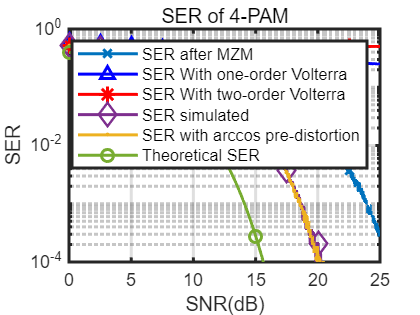


% %%%%%%% bias %%%%%%%
Vpi = 1;
% A = 0;
% B = 2;
% di = (x_2-A)/B;
%%%%%%%% MZM %%%%%%
Vdc = 1;
Vpp = 1/3; % Vout = [0,1]
% x_3_1 = w(:,1)'.*x_3;
P_3_mzm_vol_avg = 0;
x_3_1 = Y;
Vi = Vdc+Vpp*(x_3_1);

Eout3 = (cos((pi/2)*(Vi/Vpi))).*(cos((pi/2)*(Vi/Vpi)));

%     stem(x_3(1:100))
%     hold off
%     stem(x_3_1(1:100)/max(x_3_1))
%     ylim([0,1.25])
%     hold off
%     stem(abs(Eout3(1:100)))
%     ylim([0,1])
%     hold off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
AVG = 0;
Eav = mean(Eout3.^2);

x_3_1 = pulse_shape(N,symbol_rate,samples,Y);
Vi = Vdc+Vpp*(x_3_1);
Eout3 = (cos((pi/2)*(Vi/Vpi))).*conj(cos((pi/2)*(Vi/Vpi)));

for n = 1:50
    for i=1:length(dB);
        N0=Eav/2/snr(i);% calculate the power of noise
        %     N0_dB=10*log10(N0);% power of noise to dBW
        %     ni=wgn(1,N,N0_dB);% gaussian noise
        ni = sqrt(N0)*randn(1,length(Eout3)); % 1
        yR_3 = Eout3+ni;

        samplesPerSymbol = length(yR_3)/N;
        Etx_downsampled = yR_3((samplesPerSymbol/2+1):samplesPerSymbol:end);

        for k = 1:length(Etx_downsampled)
            if Etx_downsampled(k)< 1/6
                y_detect_3(k) = 0;
            elseif Etx_downsampled(k) < 1/2
                y_detect_3(k) = 1;
            elseif Etx_downsampled(k) < 5/6
                y_detect_3(k) = 2;
            else
                y_detect_3(k) = 3;
            end
        end

        bit_R_3=length(find(x_3~=y_detect_3));
        P_3_mzm_vol(i)=bit_R_3/N;% SER
    end
    AVG = P_3_mzm_vol+AVG;
end
AVG = AVG/50;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2 order

x_3_2 = Y2;
Vi = Vdc+Vpp*(x_3_2);

Eout3_2 = cos((pi/2)*(Vi/Vpi)).*conj(cos((pi/2)*(Vi/Vpi)));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Eav = mean(Eout3_2.^2);

x_3_2 = pulse_shape(N,symbol_rate,samples,Y2);
Vi = Vdc+Vpp*(x_3_2);
Eout3_2 = (cos((pi/2)*(Vi/Vpi))).*conj(cos((pi/2)*(Vi/Vpi)));

AVG2 = 0;
for n = 1:150
    for i=1:length(dB);
        N0=Eav/snr(i)/2;% calculate the power of noise
        %     N0_dB=10*log10(N0);% power of noise to dBW
        %     ni=wgn(1,N,N0_dB);% gaussian noise
        ni = sqrt(N0)*randn(1,length(Eout3_2)); % 1
        yR_3 = Eout3_2+ni;

        samplesPerSymbol = length(yR_3)/N;
        Etx_downsampled = yR_3((samplesPerSymbol/2+1):samplesPerSymbol:end);

        for k = 1:length(Etx_downsampled)
            if Etx_downsampled(k)< 1/6
                y_detect_3(k) = 0;
            elseif Etx_downsampled(k) < 1/2
                y_detect_3(k) = 1;
            elseif Etx_downsampled(k) < 5/6
                y_detect_3(k) = 2;
            else
                y_detect_3(k) = 3;
            end
        end

        bit_R_3=length(find(x_3~=y_detect_3));
        P_3_mzm_vol_2(i)=bit_R_3/N;% SER
    end
    AVG2 = P_3_mzm_vol_2+AVG2;
end
AVG2 = AVG2/150;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
semilogy(dB,P_3_mzm,'LineWidth',1.5,'Marker','x',MarkerIndices=1:deltaN:length(P_3_mzm));hold on
semilogy(dB,AVG,'blue','LineWidth',1.5,'Marker','^',MarkerIndices=1:deltaN:length(AVG));hold on
semilogy(dB,AVG2,'red','LineWidth',1.5,'Marker','*',MarkerIndices=1:deltaN:length(AVG2),MarkerSize=8);hold on
semilogy(dB,SER_4PAM,'LineWidth',1.5,'Marker','diamond',MarkerIndices=1:deltaN:length(SER_4PAM),MarkerSize=8);hold on
semilogy(dB,P_3_mzm_arc,'Color','#EDB120','LineWidth',1.5,'Marker','.',MarkerIndices=1:deltaN:length(P_3_mzm_arc))
semilogy(dB,Pb(2,:),'Color','#77AC30','LineWidth',1.5,'Marker','o',MarkerIndices=1:deltaN:length(SER_4PAM));grid on;
ylim([10^-4,1])
xlabel('SNR(dB)')
ylabel('SER')
set(gca,'LineWidth',1.5)
legend('SER after MZM','SER With one-order Volterra','SER With two-order Volterra','SER simulated','SER with arccos pre-distortion','Theoretical SER')
title('SER of 4-PAM')
grid on
hold off

% % 8-PAM signal
% % volterra
% input = x_4;
% input(input==5) = 5/7; input(input==4) = 4/7; input(input==1) = 1/7;
% input(input==6) = 6/7; input(input==3) = 3/7;
% input(input==7) = 1; input(input==2) = 2/7;
% X = x_4;
% Y = x_4;
% w = rand(N,L);
% mse = zeros(1,loopnum);
% for i = 1:loopnum
%     %%%%%%%%%%%%%%%%% MZM %%%%%%%%%%%%%%%%%%%%
%     Vdc = 3;
%     Vpp = 1/7; % Vout = [0,1]
%     x_input = Y;
%     Vi = Vdc+Vpp*(x_input);
%
%     Eout4 = (cos((pi/2)*(Vi/Vpi)));
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%     for j=1:N
%         X_shift = circshift(X,-j+1,2);
%         for l = 1:L
%             X_in = circshift(X_shift,l-1,2);
%             x(l,j) = X_in(1);
%         end
%         Y(j) = sum(w(j,:)*x(:,j));
%         e(j) = Eout4(j)-input(j); % error calculate
%         w(j,:) = w(j,:) + e(j)*mu*2*x(:,j)'; % parameter renewal
%         Y(j) = sum(w(j,:)*x(:,j));
%     end
%     mse(i) = sum(abs(e.^2))/N;
% %     end
% end
% plot(mse)
% xlim([2,150])
% hold off

% % 8PAM
% % %%%%%%% bias %%%%%%%
% Vpi = 1;
% % A = 0;
% % B = 2;
% % di = (x_2-A)/B;
% %%%%%%%% MZM %%%%%%
% Vdc = 3;
% Vpp = 1/7; % Vout = [0,1]
% x_4_1 = Y/max(Y);
% Vi = Vdc+Vpp*(Y);
%
% Eout4 = (cos((pi/2)*(Vi/Vpi)));
% stem(x_4(1:100))
% hold off
% stem(x_4_1(1:100))
% ylim([0,1])
% hold off
% stem(Eout4(1:100))
% hold off
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%
% for i=1:length(dB);
%     N0=E(8)/snr(i);%计算噪声功率
%     N0_dB=10*log10(N0);%将噪声功率转换为dBW
%     ni=wgn(1,N,N0_dB);%产生高斯噪声
%     yR_4 = Eout4+ni;
%
%
%     for k = 1:length(yR_4)
%         if yR_4(k)< 1/14
%             y_detect_4(k) = 0;
%         elseif yR_4(k) < 3/14
%             y_detect_4(k) = 1;
%         elseif yR_4(k) < 5/14
%             y_detect_4(k) = 2;
%         elseif yR_4(k) < 7/14
%             y_detect_4(k) = 3;
%         elseif yR_4(k) < 9/14
%             y_detect_4(k) = 4;
%         elseif yR_4(k) < 11/14
%             y_detect_4(k) = 5;
%         elseif yR_4(k) < 13/14
%             y_detect_4(k) = 6;
%         else
%             y_detect_4(k) = 7;
%         end
%     end
%
%     bit_R_4=length(find(x_4~=y_detect_4));% Number of error bits
%     P_4_mzm_vol(i)=bit_R_4/N;% SER
% end

% figure;
% semilogy(dB(1:deltaN:end),P_4_mzm(1:deltaN:end),'.-','LineWidth',1.2);hold on
% semilogy(dB(1:deltaN:end),P_4_mzm_vol(1:deltaN:end),'b*','LineWidth',1.2);hold on
% semilogy(dB(1:deltaN:end),P_4(1:deltaN:end),'--o','LineWidth',1.5);hold on
% semilogy(dB,Pb(3,:),'-.r','LineWidth',1.5);grid on;
% ylim([10^-2,1])
% legend('SER after MZM','SER With Volterra','SER simulated','SER theory')
% title('SER of 8-PAM')
% grid on
% hold off

%% 2-order
% intial kernel and input data
% input = x_4;
% loopnum = 1000;
% input(input==5) = 5/7; input(input==4) = 4/7; input(input==1) = 1/7;
% input(input==6) = 6/7; input(input==3) = 3/7;
% input(input==7) = 1; input(input==2) = 2/7;
% X2 = x_4;
% Y2 = x_4;
% w2 = ones(N,L^2);
% mse2 = zeros(1,loopnum);
%
% %% two order volterra
% for i = 1:loopnum
%     %%%%%%%%%%%%%%%% MZM %%%%%%%%%%%%%%%%%%%%
%     Vdc = 3;
%     Vpp = 1/7; % Vout = [0,1]
%     x_input = Y2;
%     Vi = Vdc+Vpp*(x_input);
%
%     Eout4 = (cos((pi/2)*(Vi/Vpi)));
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     for j=1:N
%         X2_shift = circshift(X2,-j+1,2);
%         for l = 1:L^2
%             index = fix((l-1)/L);
%             if index<1
%                 X2_in = X2_shift.*circshift(X2_shift,l-1,2);
%                 x2(l,j) = X2_in(1);
%             elseif index >= 1
%                 X2_shift2 = circshift(X2_shift,-index*L,2);
%                 X2_in = X2_shift2.*circshift(X2_shift,l-1,2);
%                 x2(l,j) = X2_in(1);
%             end
%         end
%         Y2(j) = sum(w2(j,:)*x2(:,j));
%         e2(j) = Eout4(j)-input(j); % error calculate
%         w2(j,:) = w2(j,:) + e2(j)*mu*2*x2(:,j)'; %parameter renewal
%         Y2(j) = sum(w2(j,:)*x2(:,j));
%     end
%     mse2(i) = sum(abs(e2).^2)/N;
% end

% plot(mse2)
% xlim([0,150])
% hold off

% % 8PAM
% % %%%%%%% bias %%%%%%%
% Vpi = 1;
% % A = 0;
% % B = 2;
% % di = (x_2-A)/B;
% %%%%%%%% MZM %%%%%%
% Vdc = 3;
% Vpp = 1/7; % Vout = [0,1]
% x_4_1 = Y2;
% Vi = Vdc+Vpp*(Y2);
%
% figure
% Eout4 = (cos((pi/2)*(Vi/Vpi)));
% plot(x_4_1(1:100))
% hold off
% plot(Eout4(1:100))
% hold off
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%
% for i=1:length(dB);
%     N0=E(8)/snr(i);%计算噪声功率
%     N0_dB=10*log10(N0);%将噪声功率转换为dBW
%     ni=wgn(1,N,N0_dB);%产生高斯噪声
%     yR_4 = Eout4+ni;
%
%
%     for k = 1:length(yR_4)
%         if yR_4(k)< 1/14
%             y_detect_4(k) = 0;
%         elseif yR_4(k) < 3/14
%             y_detect_4(k) = 1;
%         elseif yR_4(k) < 5/14
%             y_detect_4(k) = 2;
%         elseif yR_4(k) < 7/14
%             y_detect_4(k) = 3;
%         elseif yR_4(k) < 9/14
%             y_detect_4(k) = 4;
%         elseif yR_4(k) < 11/14
%             y_detect_4(k) = 5;
%         elseif yR_4(k) < 13/14
%             y_detect_4(k) = 6;
%         else
%             y_detect_4(k) = 7;
%         end
%     end
%
%     bit_R_4=length(find(x_4~=y_detect_4));% Number of error bits
%     P_4_mzm(i)=bit_R_4/N;% SER
% end

% figure;
% semilogy(dB(1:deltaN:end),P_4_mzm(1:deltaN:end),'b-*','LineWidth',1.2);hold on
% semilogy(dB(1:deltaN:end),P_4(1:deltaN:end),'--o','LineWidth',1.5);hold on
% semilogy(dB,Pb(3,:),'-.r','LineWidth',1.5);grid on;
% ylim([10^-3,1])
% hold off


nQuantBits = 12;

nQuantLevels = 2^nQuantBits;



qRange_Tx = (max(TX_signal)-min(Tx_signal)); %Tx_signal is the signal before the DAC

qNoiseInt_Tx = qRange_Tx/nQuantLevels;

qNoiseVariance_Tx = qNoiseInt_Tx.^2/12;

qNoise_Tx = unifrnd(-qNoiseInt_Tx/2,qNoiseInt_Tx /2,size(Tx_signal))+1j*unifrnd(-qNoiseInt_Tx /2,qNoiseInt_Tx /2,size(Tx_signal)); % you add this noise to Tx_signal



qRange_Rx = (max(RX_signal)-min(Rx_signal)); %Rx_signal is the signal before the ADC

qNoiseInt_Rx = qRange_Rx/nQuantLevels;

qNoiseVariance_Rx = qNoiseInt_Rx.^2/12;

qNoise_Rx = unifrnd(-qNoiseInt_Rx /2,qNoiseInt_Rx /2,size(Rx_signal))+1j*unifrnd(-qNoiseInt_Rx /2,qNoiseInt_Rx /2,size(Rx_signal)); % you add this noise to Rx_signal